# Lab 2

## Kurt Delegard

## PHYS 434 AB

Let us assume we are using a telescope to observe gamma rays emitted by a distant source. The background distribution of cosmic rays hitting our telescope every day has an approximately Poisson distribution. Let us also assume that our telescope measures, on average, 1.2 cosmic rays per day, and that the source we are interested in emits 4 gamma rays every day.

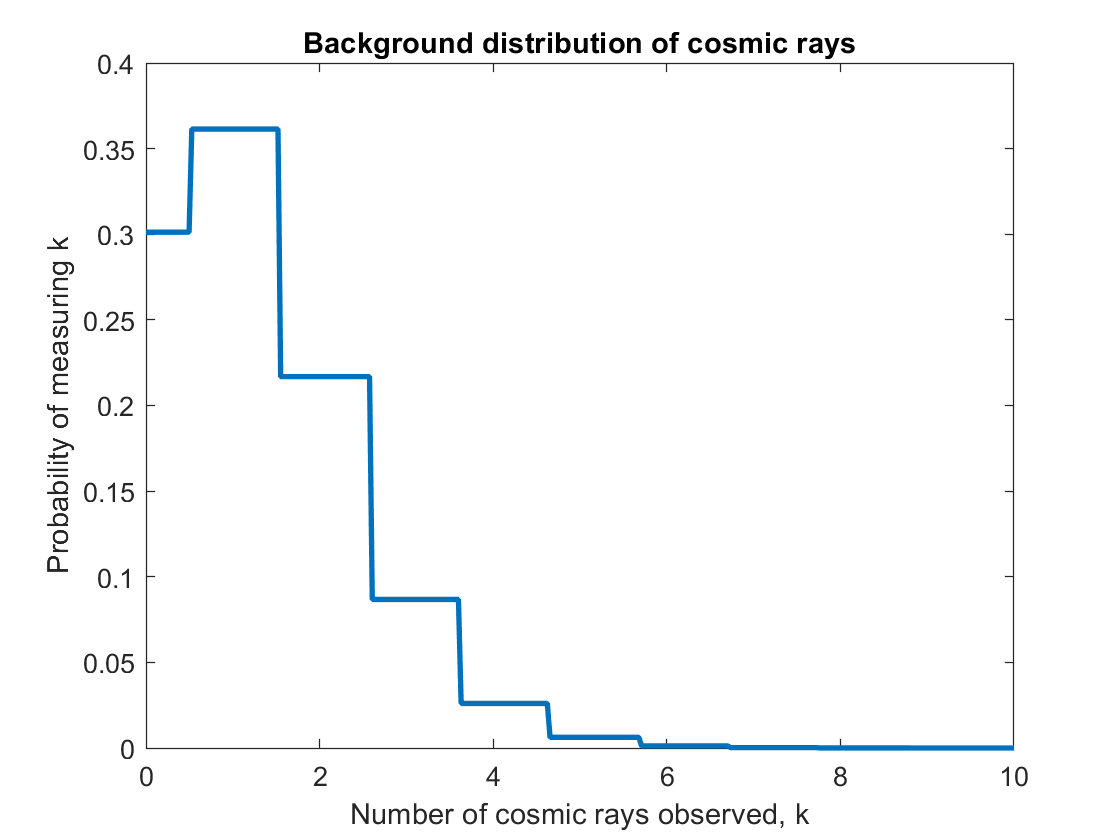

clear;
clf;

%Average cosmic rays per day (background)
X = 1.2;

%Average number of gamma ray emitted by source
Y = 4.0;

pd_bkg = makedist('Poisson', X);
xs = 0:30;
pd_ys = pdf(pd_bkg, xs);

[pdxs1, pdys1] = pdfplot(xs, pd_ys);
plot(pdxs1, pdys1, 'linewidth', 2);
title('Background distribution of cosmic rays');
xlabel('Number of cosmic rays observed, k');
ylabel('Probability of measuring k');
xlim([0 10])

Now we will see how the probability distribution changes as we convolve (sum) the background distribution over more days:

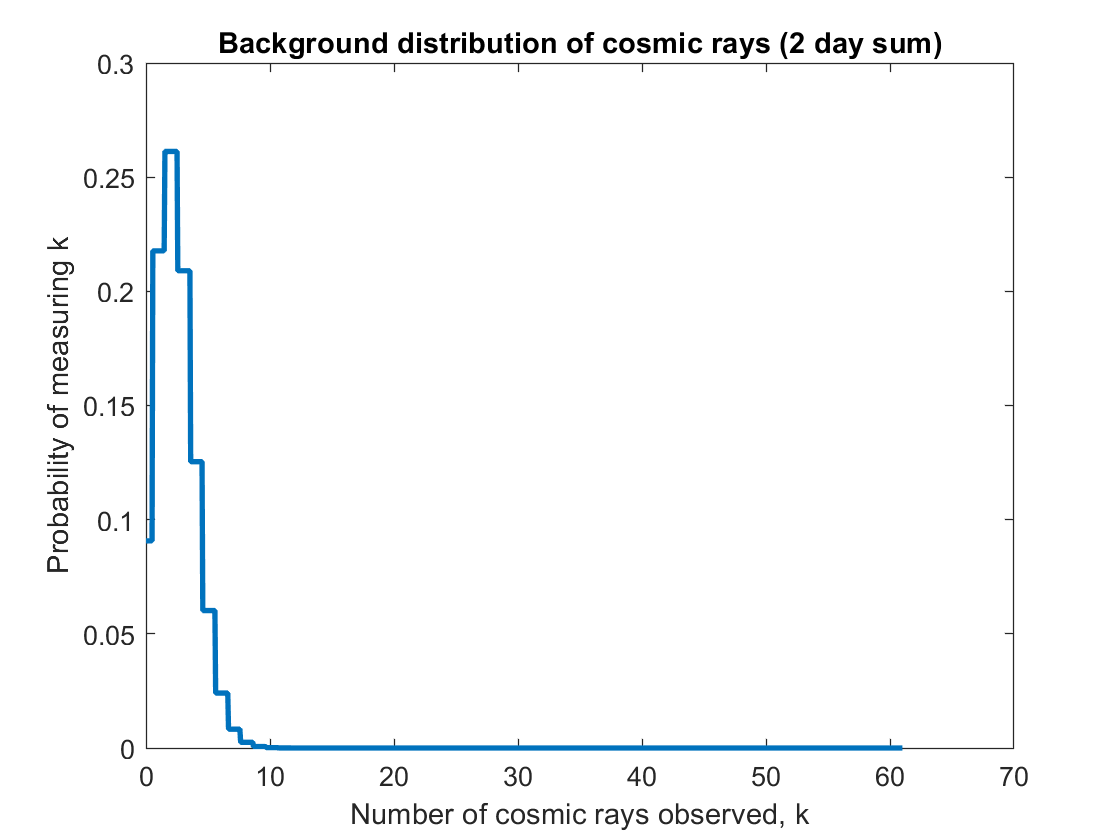

clf;
day_2_pdf = conv(pd_ys, pd_ys);

[pdxs2, pdys2] = pdfplot(xs, day_2_pdf);
plot(pdxs2, pdys2, 'linewidth', 2);
title('Background distribution of cosmic rays (2 day sum)');
xlabel('Number of cosmic rays observed, k');
ylabel('Probability of measuring k');

The distribution is still very skewed to the left. Note the finer range of x-values as a result of convoluting the original distribution:


$$P_{A+B} \left(x^{\prime } \right)=\sum_z P_A \left(z\right)*P_B \left(x-z\right)=P_A \left(x\right)*P_B \left(x\right)$$


By convolving two distributions together with values x, the resulting distribution will have values x' corresponding to the values x-z, which provides data for points between the original values of x.

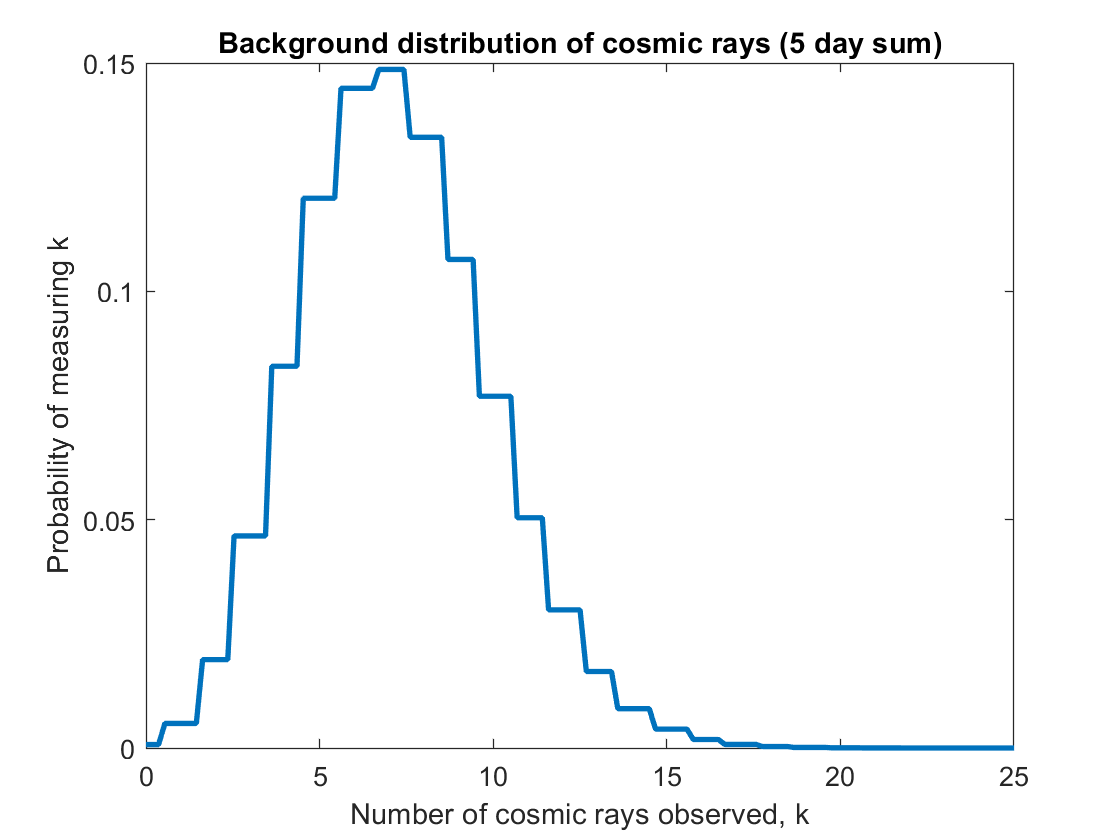

clf;
day_5_pdf = pd_ys;
for ii = 1:5
    day_5_pdf = conv(day_5_pdf, pd_ys);
end

[pdxs5, pdys5] = pdfplot(0, day_5_pdf);
plot(pdxs5, pdys5, 'linewidth', 2);
title('Background distribution of cosmic rays (5 day sum)');
xlabel('Number of cosmic rays observed, k');
ylabel('Probability of measuring k');
xlim([0 25])

Here the peak has shifted slightly to the right and the range of x values has become even more fine. The distribution has widened and now covers a larger range of x-values.

We know that as one sums or averages a distribution many times, the convolved distribution will become Gaussian in shape. Is the Poisson distribution - summed over five days - Gaussian at this point?

The logarithm of a normally distributed variable will appear to be parabolic. Let's compare the shape of our convolved distribution with a Gaussian distribution with approximately the same shape and position:

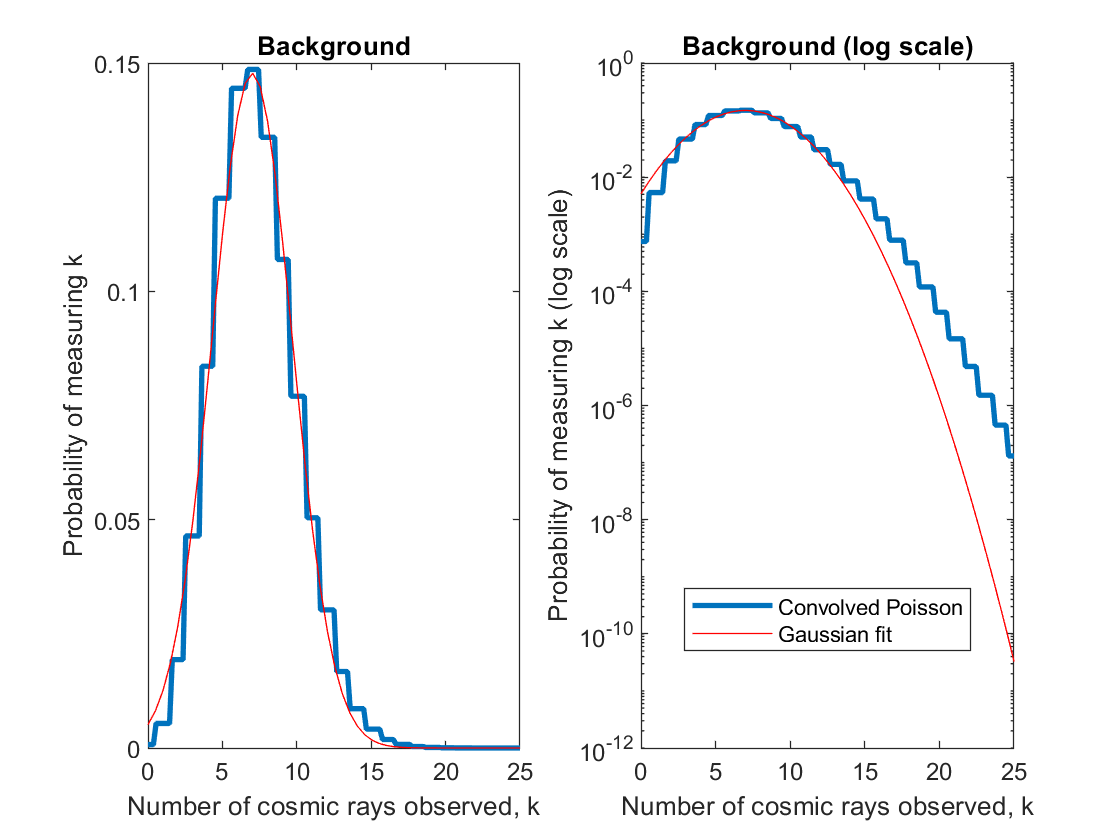

subplot(1, 2, 1);

plot(pdxs5, pdys5, 'linewidth', 2);
hold on;
normxs = linspace(0, 100, 200);
normys = normpdf(normxs, 7, 2.7);
plot(normxs, normys, 'r-')
title('Background');
xlabel('Number of cosmic rays observed, k');
ylabel('Probability of measuring k');
xlim([0, 25]);

subplot(1, 2, 2);

plot(pdxs5, pdys5, 'linewidth', 2);
hold on;
plot(normxs, normys, 'r-')
set(gca,'YScale','log')
title('Background (log scale)');
xlabel('Number of cosmic rays observed, k');
ylabel('Probability of measuring k (log scale)');
legend('Convolved Poisson', 'Gaussian fit', 'location', 'best');
xlim([0, 25]);

The distribution after five days is still Poisson in shape; the distribution does not follow a Gaussian trend very accurately.

From a mathematical point of view, the convolution of multiple Poisson distributions [is a Poisson distribution with](https://en.wikipedia.org/wiki/List_of_convolutions_of_probability_distributions#Discrete_distributions) $\lambda_i =\sum_{i=1}^n \lambda_i$, that is, a Poisson distribution with $\lambda$ equal to the sum of the $\lambda$s of the convolved distributions. Since we are only convolving the original Poisson distribution multiple times, after N convolutions, $\lambda_i =N*\lambda$. Furthermore, Poisson distributions will appear more Gaussian in shape as $\lambda$ increases. Therefore, the larger N is, the larger $\lambda_i =N*\lambda$ will be, and therefore the more Gaussian the resulting distribution will appear.

Following this statement, will the distribution look Gaussian after 200 days?

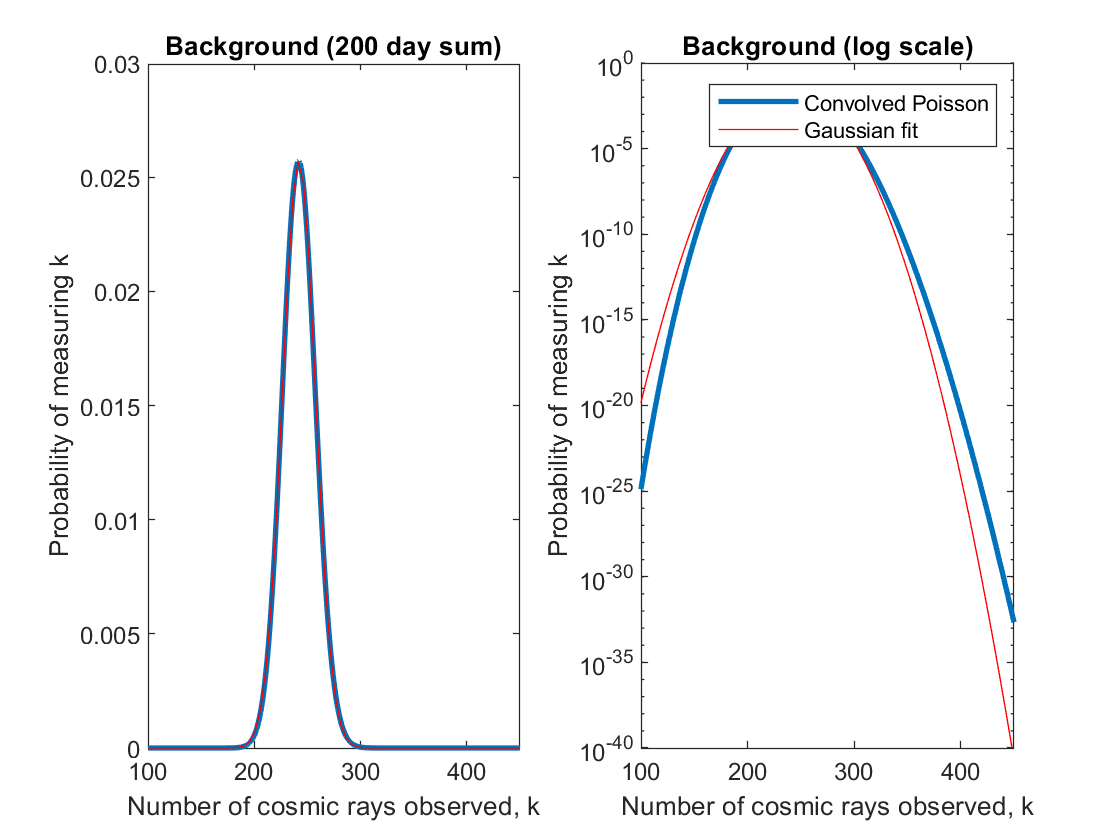

clf;
day_200_pdf = pd_ys;
for ii = 1:200
    day_200_pdf = conv(day_200_pdf, pd_ys);
end

subplot(1, 2, 1);

plot(1:length(day_200_pdf), day_200_pdf, 'linewidth', 2);
hold on;

normxs = linspace(0, 1000, 200);
[mu, sigma] = pdfstats(day_200_pdf);
normys = normpdf(normxs, mu, 15.5);
plot(normxs, normys, 'r-');
title('Background (200 day sum)');
xlabel('Number of cosmic rays observed, k');
ylabel('Probability of measuring k');
xlim([100 450]);

subplot(1, 2, 2);
plot(1:length(day_200_pdf), day_200_pdf, 'linewidth', 2);
hold on;

plot(normxs, normys, 'r-');
set(gca,'YScale','log')
title('Background (log scale)');
xlabel('Number of cosmic rays observed, k');
ylabel('Probability of measuring k');
legend('Convolved Poisson', 'Gaussian fit');
xlim([100 450]);

While the distribution not quite yet a Gaussian distribution, we can clearly see that by summing the distribution for more days, the distribution approaches a Gaussian distribution, as predicted by the Central Limit Theorem.

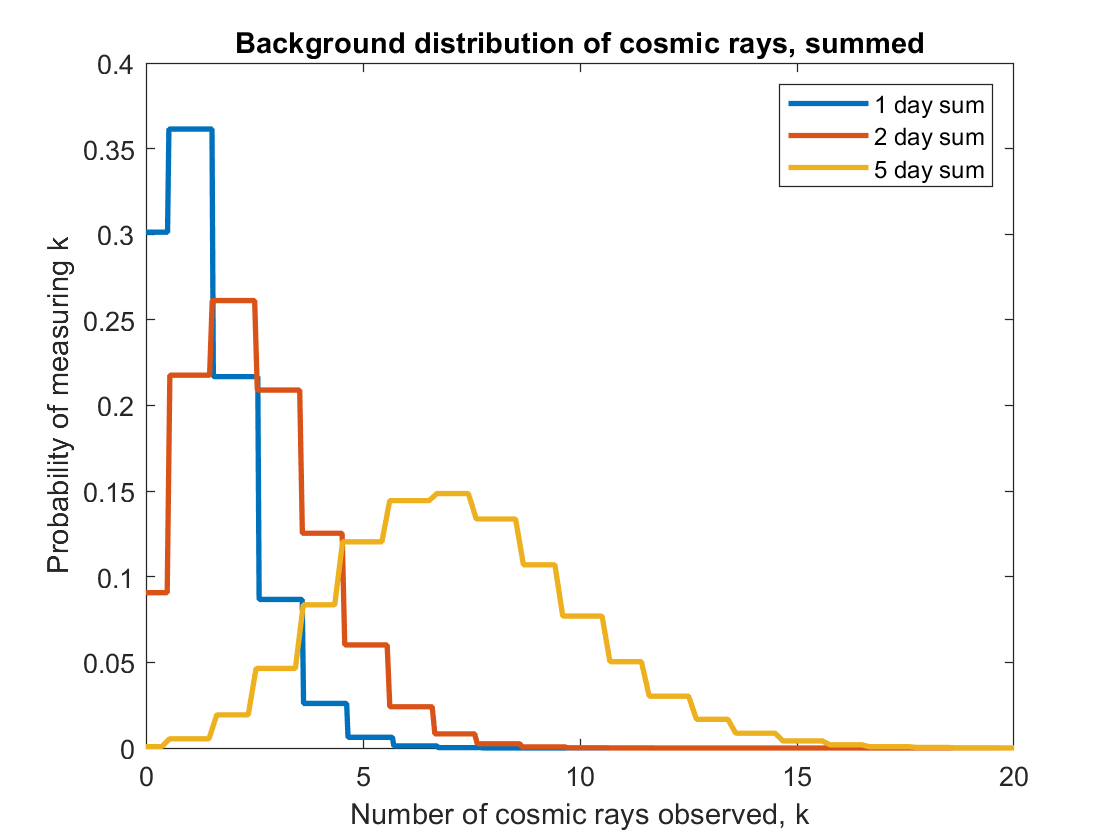

clf;
plot(pdxs1, pdys1, 'linewidth', 2), hold on;
plot(pdxs2, pdys2, 'linewidth', 2);
plot(pdxs5, pdys5, 'linewidth', 2);
xlim([0, 20]);

title('Background distribution of cosmic rays, summed');
xlabel('Number of cosmic rays observed, k');
ylabel('Probability of measuring k')
legend('1 day sum', '2 day sum', '5 day sum');

Now we will show the evolution of the distribution as we average it over several days. To average the distribution over several days, we use the convolution theorem: $P_{A+B} \left(x\right)=\sum_z P_A \left(z\right)*P_B \left(x-z\right)=P_A \left(x\right)*P_B \left(x\right)$. When averaging over N random variables *x*, one sums the distributions via convolution, then divides the resulting *x* by N.

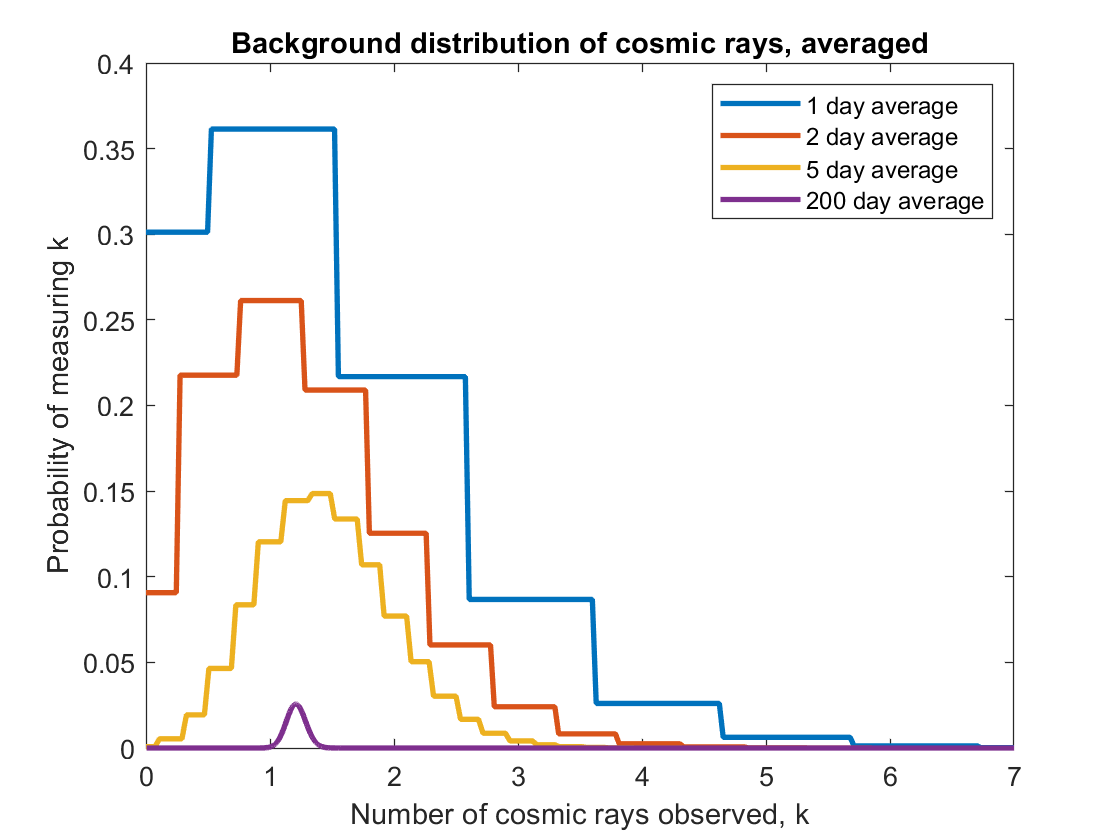

clf;

plot(pdxs1, pdys1, 'linewidth', 2);
hold on;
title('Background distribution of cosmic rays, averaged');
xlabel('Number of cosmic rays observed, k');
ylabel('Probability of measuring k');
plot(pdxs2/2, pdys2, 'linewidth', 2);
plot(pdxs5/5, pdys5, 'linewidth', 2);
plot((1:length(day_200_pdf))./200, day_200_pdf, 'linewidth', 2);
xlim([0 7])
legend('1 day average', '2 day average', '5 day average', '200 day average');

As the original distribution is averaged over more days, iwe can see several trends in the resulting distributions:

- The maximum of the peak gets smaller. 

- The distance between values of x gets smaller.

- The distribution approaches a Gaussian shape.

- The peak of each distribution is centered around $\lambda =1\ldotp 2$, the average value of the original distribution.

These trends reflect what we saw when the distributions were summed, only now the distrbutions are slightly thinner (since the range of x values for each is divided by N) and are all centered around the same mean. These trends also reflect the Central Limit Theorem - that as one averages or sums a distribution increasingly many times, the distribution will converge to a Gaussian. As the original distribution is averaged over more days, the resulting distribution clearly is more Gaussian than a distribution averaged over fewer days.

Now, we will assume we have waited for N = 5 days, and saw 4 gamma rays per day during that period, on average. 

n = 5;
signal = Y * n

signal = 20

From this observation, we can pose the following statistical question: **Given that the signal we have over 5 days is 20 gamma rays, what its the probability that the background produced a reading that is as signal-like or more than this?**

The steps to solving this question are as follows:

- Integrate the summed background pdf from 0 to 20 to find the probability that the background did not produce the signal.

- Subtract this from 1 to find the probabilty that the background did produce the signal.

- Turn this probability into a sigma value.

We can use the value of the cumulative distribution function at x = 20 to get the integral of the pdf from $-\infty$ to 20. As stated before, the convolution of multiple Poisson distributions is equivalent to a Poisson distribution with $\lambda_i =\sum_{i=1}^n \lambda_i =N*\lambda_i$, so we will use the cdf() command with a Poisson distribution with $\lambda =5*\lambda_i$:

day_5_cdf = cdf('Poisson', 1:length(day_5_pdf), 5*X)

day_5_cdf =     0.0174    0.0620    0.1512    0.2851    0.4457    0.6063    0.7440    0.8472    0.9161    0.9574    0.9799    0.9912    0.9964    0.9986    0.9995    0.9998    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


This is the probability that the background did not produce the signal; i.e. that the background gave a reading that is as signal-like or less than 20. To get the probability that the background did produce the signal, we subtract this from 1:

prob_signal = 1-day_5_cdf(signal-1)

prob_signal = 5.1802e-06

To convert this probability into a sigma value on a normal distribution, we use norminv():

sigma = norminv(prob_signal)

sigma = -4.4095

This observation is considered a 4.4 sigma event. Given that in many applications of physics, 5 sigma is required to consider an event to be significant, this event is not quite big enough to be considered significant.

## Problem 2

Now we will observe how a skewed distribution (in particular, a Rayleigh distribution) changes as we average over several observing intervals.

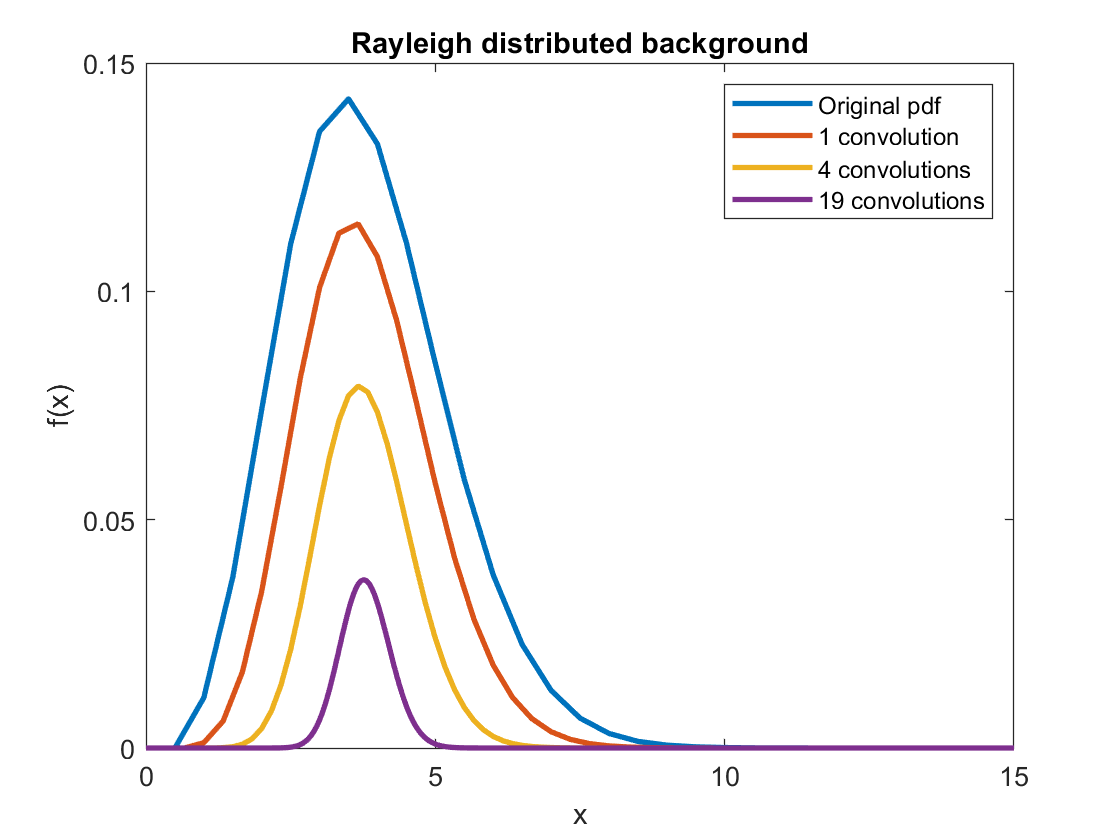

clear;
clc;

%sigma:
s = 3;

clf;
options.linewidth = 2; 
[rx1, ry1] = rayleighconv(1, s);
plot(rx1, ry1, options), hold on;
[rx2, ry2] = rayleighconv(2, s);
plot(rx2, ry2, options);
[rx5, ry5] = rayleighconv(5, s);
plot(rx5, ry5, options);
[rx20, ry20] = rayleighconv(20, s);
plot(rx20, ry20, options);
title('Rayleigh distributed background');
xlabel('x');
ylabel('f(x)')
legend('Original pdf', '1 convolution', '4 convolutions','19 convolutions');

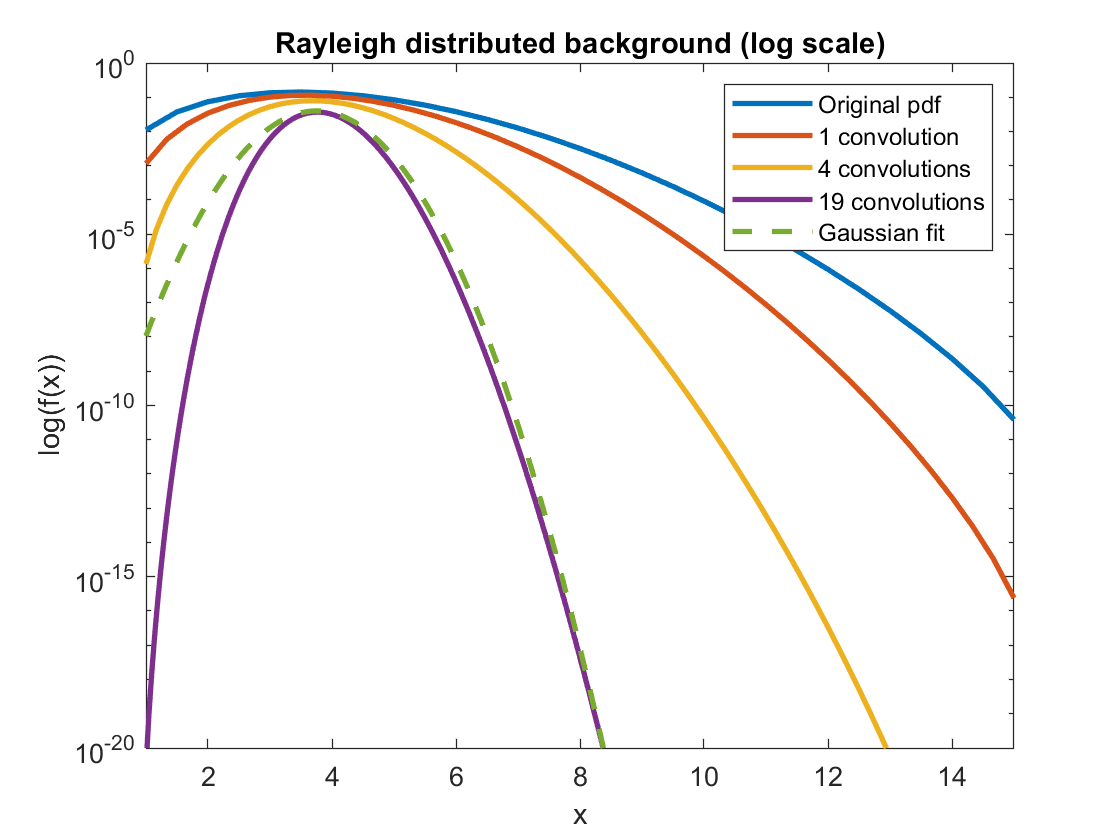

clf;
plot(rx1, ry1, options), hold on;
plot(rx2, ry2, options);
plot(rx5, ry5, options);
plot(rx20, ry20, options);
set(gca,'YScale','log');
ylim([1e-20 1]);
xlim([1 15]);
normys = normpdf(rx20, 3.75, 0.5) ./ 20;
plot(rx20, normys, '--', 'linewidth', 2);
title('Rayleigh distributed background (log scale)');
xlabel('x');
ylabel('log(f(x))')
legend('Original pdf', '1 convolution', '4 convolutions','19 convolutions', 'Gaussian fit');

The distribution clearly approaches a Gaussian shape as the number of convolutions increases, but even after 19 convolutions it is not quite Gaussian. What about after 150 observing intervals?

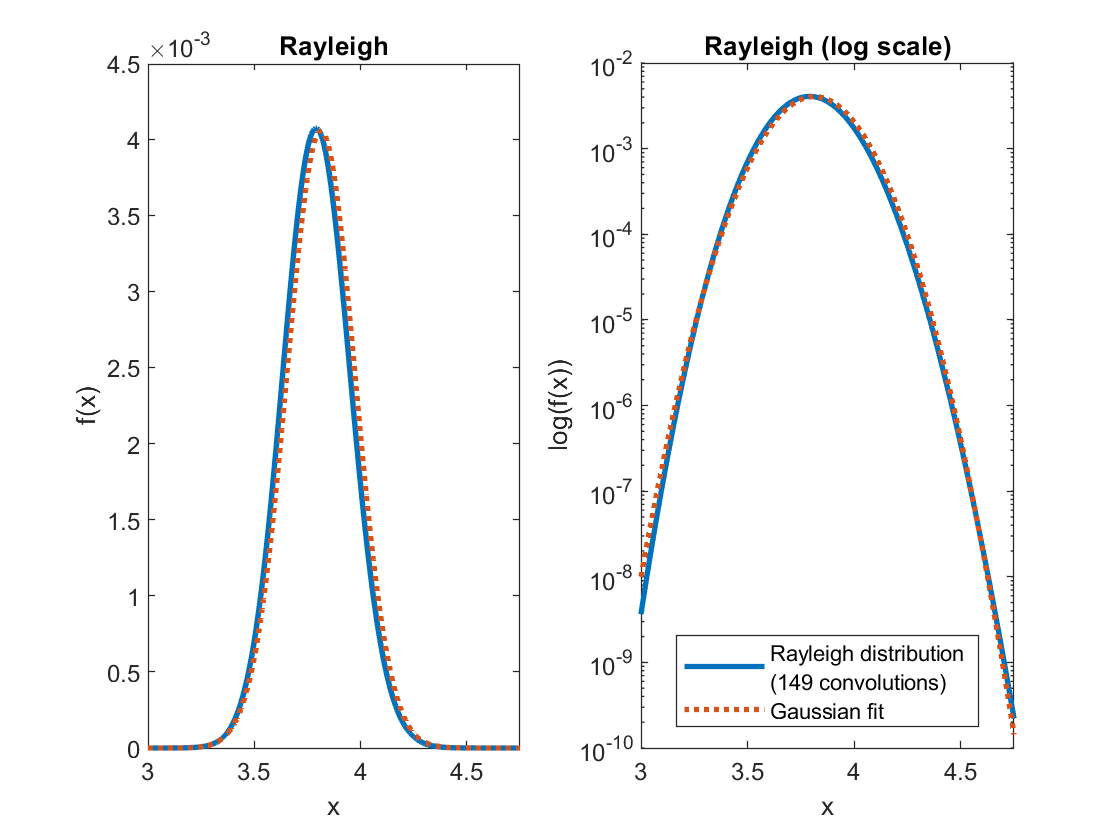

clf;
[rx150, ry150] = rayleighconv(150, s);

subplot(1, 2, 1);
plot(rx150, ry150, 'linewidth', 2), hold on;
normys = normpdf(rx150, 3.813, 0.16) ./ 615;
plot(rx150, normys, ':', 'linewidth', 2);
xlim([3, 4.75]);
title('Rayleigh');
xlabel('x');
ylabel('f(x)')

subplot(1, 2, 2);
plot(rx150, ry150, 'linewidth', 2), hold on;
plot(rx150, normys, ':', 'linewidth', 2);
xlim([3, 4.75]);
set(gca,'YScale','log');
legend('Rayleigh distribution \newline(149 convolutions)', 'Gaussian fit', 'location', 'south')
title('Rayleigh (log scale)');
xlabel('x');
ylabel('log(f(x))')

Now the distribution is clearly Gaussian.

## Problem 3

Let us consider the thermal background distribution of SWIFT, an X-ray/ultraviolet satellite telescope. Assuming the background distribution is a zero-mean Gaussian with a fixed width over the image, $\sigma =3$, we will analyze the significance of data that SWIFT reads compared to the background.

### Version 1:

We have received data from LIGO indicating a gravitational wave signal, and the associated UV light is seen by SWIFT. Because of SWIFT's accuracy, we only need to look for a signal within 1 pixel out of the entire image in its view. Assuming the signal is of strength 16, what is the significance of this event? In other words,** what is the probability that the thermal background produced a reading that is as signal-like or more than the signal seen by LIGO and SWIFT?**

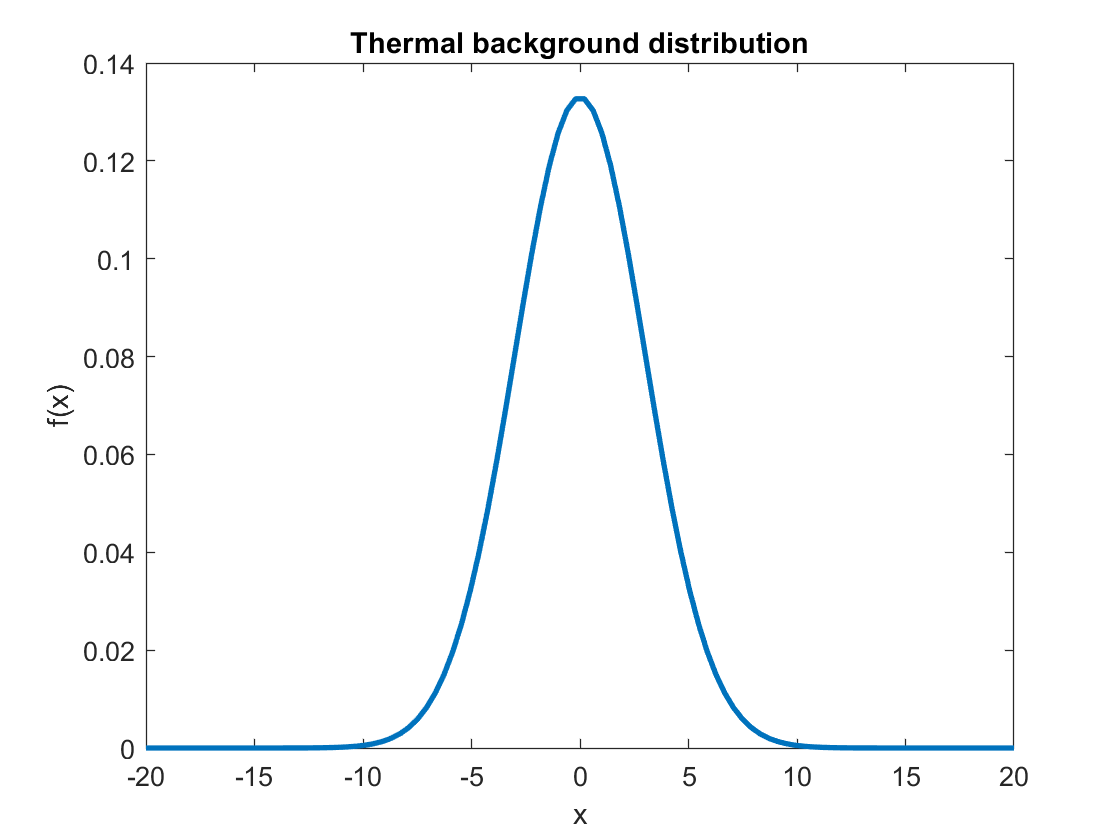

clc;
clear;
clf;

%width of Gaussian distribution:
X = 3;

%Signal strength:
Y = 16;

mu = 0;

xs = linspace(-20, 20, 100);
ys = normpdf(xs, mu, X);
plot(xs, ys, 'linewidth', 2), hold on;
plot([X X], [0 ys(X)], 'r-', 'linewidth', 2);
title('Thermal background distribution');
xlabel('x');
ylabel('f(x)');

Note that this distribution is the thermal background of only one pixel.

We first need to integrate the pdf from 0 to 16 to find the probability that the background did not produce the signal.

prob_bkg = cdf("Normal", Y, mu, X)

prob_bkg = 1.0000

We subtract this from 1 to find the probability that the background did produce the signal.

prob_signal = 1-prob_bkg

prob_signal = 4.8213e-08

Finally, we convert this probability to a sigma value:

sigma = abs(norminv(prob_signal))

sigma = 5.3333

Assuming a signal with over 5 sigma is considered significant, we can call this particular event a discovery.

### Version 2

This time, we have received data from LIGO indicating a gravitational wave signal, but there is no associated data from SWIFT. This means the event could have happened in any of the 10,000 pixels in SWIFT's view. **What is the probability that the thermal background produced a reading that is as signal-like or more than the signal seen by LIGO and SWIFT ****in any of the 10,000 pixels****?**

We can find the probability distribution of 10,000 pixels by asking an identical, but lengthier question: what is the probability that the thermal background produced a reading of 16 or more in pixel 1, or pixel 2, or pixel 3... or pixel 10,000? The formula $P_{A\;\mathrm{or}\;B} =P_A +P_B -P_A *P_B$ gives us the probability that a signal was produced by the probability distributions in pixel A or pixel B. The probability distribution of each pixel is identical, so $P_B =P_A$. Furthermore, $P_A$ is very small - the probability we found in the previous problem, $4\ldotp 82*{10}^{-8}$ - so $P_A *P_A$ is negligible. This results in the probability distribution for two pixels: $P_2 \approx P_1 +P_1$. From this we can see that $P_{10,000} \approx \sum_{i=1}^{10,000} P_i =10,000*P_1$.

The background probability distribution over 10,000 pixels is simply the background pdf of one pixel multiplied 10,000 times. Since the probability of significance in one pixel was very small, we can approximate the probability of significance in 10,000 pixels as:

prob_10k = 10000 * prob_signal

prob_10k = 4.8213e-04

The sigma value associated with this probability is:

sigma_10k = norminv(prob_10k)

sigma_10k = -3.3008

We can no longer claim this event as a discovery if we do not know which pixel to look at.

## Problem 4

What *exactly* is the signal strength required to claim significance in the previous problem (version 1 and version 2)? In other words, **what is the signal strength that would equate to a 5-sigma event on the background pdf?**

If we know which pixel to look at:

clear;
clc;

X = 3;

sigma = -5;

We can find the probability associated with this value of sigma from the value of the complementary distribution function at x = 5:

p = normcdf(sigma, 0, 1)

p = 2.8665e-07

Then we can find the upper bound on the integral that would have produced an area equal to this probability. This can be done by using the inverse cumulative distribution function for our pdf:

signal = abs(icdf('normal', p, 0, 3))

signal = 15

This value seems to make sense - we assumed a signal strength of 16 in the problem, and such a signal had $\sigma =5\ldotp 3333$.

In the case that we do not know which pixel to look at, for 10,000 pixels we assumed that $P_{10,000} =10,000*P_1$, so:

p_10k = p / 10000

p_10k = 2.8665e-11

signal_10k = abs(icdf('normal', p_10k, 0, 3))

signal_10k = 19.6516

signal_10k/signal

ans = 1.3101

To claim the discovery of an event by looking at 10,000 pixels, we would need to observe a signal strength of 19.65 or higher, which is 1.31 times brighter than if we only looked at one pixel for a signal. One would think that if we increase our trials by 10,000, we would need to be 10,000 times more sensitive to a possible signal. However, it must be noted that it is not the signal strength or sigma that changes by 10,000, but the probability:

p / p_10k

ans = 10000

Since the probability corresponds to an area under the pdf, the projection of that area on to the x-axis will be smaller than 10,000, and thus the signal threshold will change by less than 10,000. However, the more we increase the number of trials, the further we extend into the tail of the distribution, where the x-projection grows exponentially larger. We therefore expect that the required signal strength increases exponentially as we increase the number of trials:

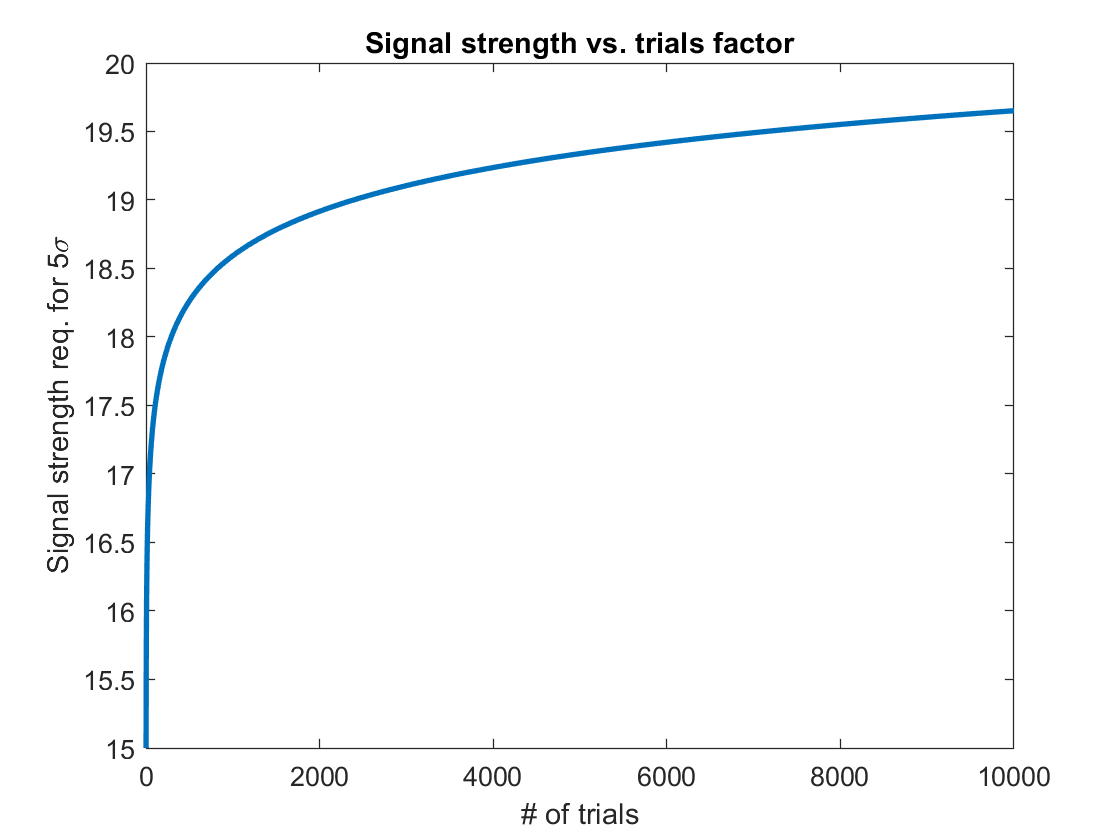

trials = logspace(0, 4, 1000);
signal_strength = @(trials) abs(icdf('normal', p ./ trials, 0, 3));
clf;
plot(trials, signal_strength(trials), 'linewidth', 2);
title('Signal strength vs. trials factor')
xlabel('# of trials');
ylabel('Signal strength req. for 5{\sigma}')

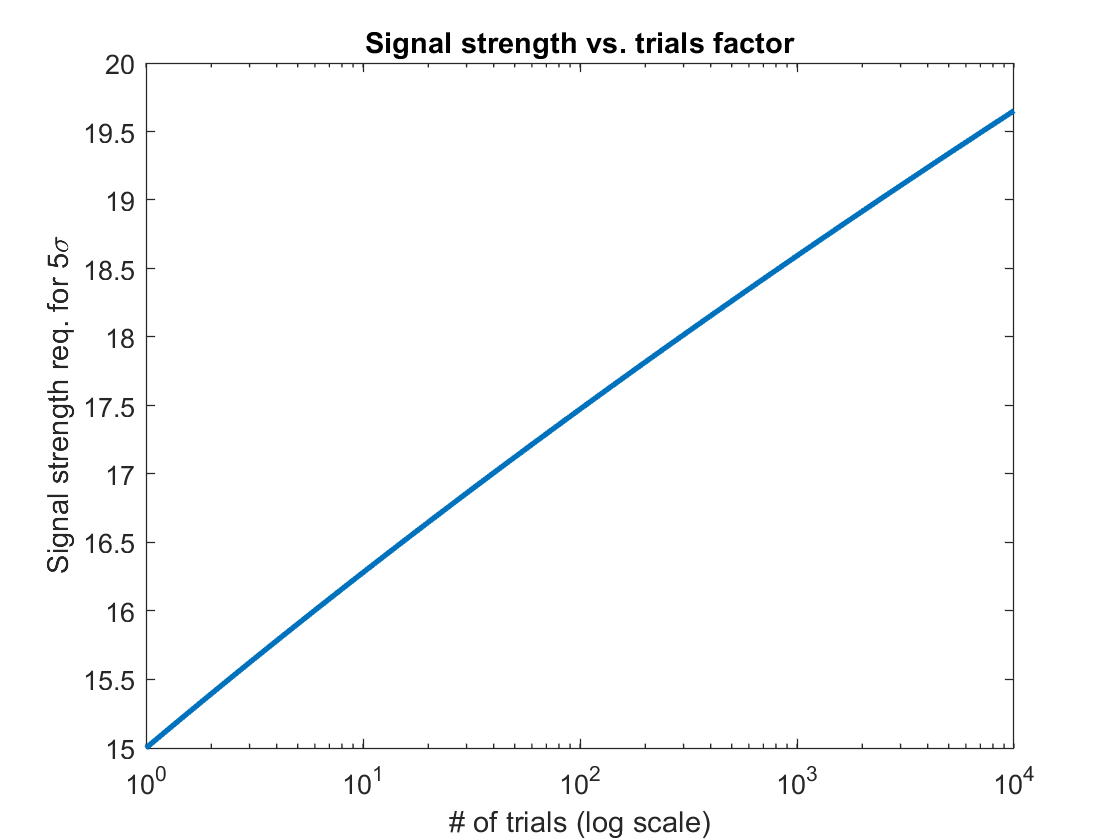

clf;
semilogx(trials, signal_strength(trials), 'linewidth', 2);
title('Signal strength vs. trials factor')
xlabel('# of trials (log scale)');
ylabel('Signal strength req. for 5{\sigma}')

Our observations match with what we expected; the required signal strength for a $5\sigma$ event increases exponentially as the number of trials increases.

What if we were to use a non-Gaussian distribution for our background in the first place, for example, a Chi-Squared distribution? Let's first test this distribution by looking for significance in a signal strength of 16.

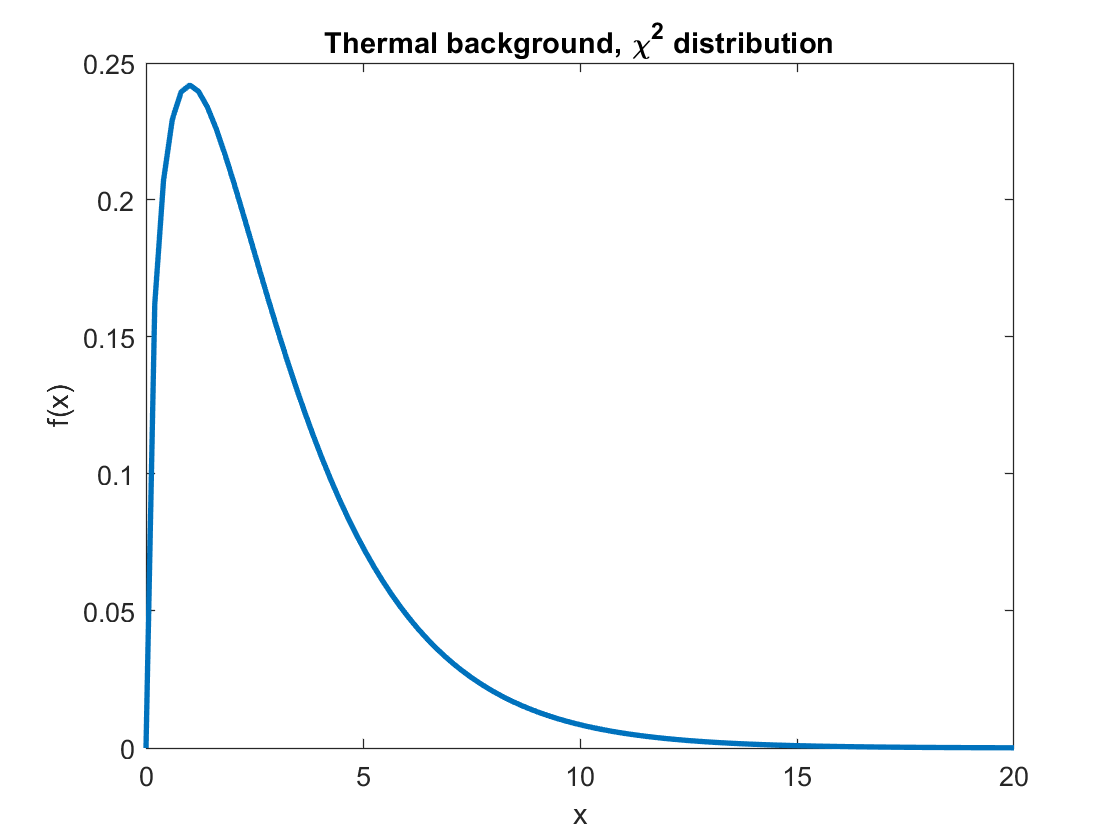

clc;
clear;
clf;

%Degrees of freedom of chi-squared:
X = 3;

%Signal strength:
Y = 16;

xs = linspace(0, 20, 100);
ys = chi2pdf(xs, X);
plot(xs, ys, 'linewidth', 2);
title('Thermal background, {\chi^2} distribution');
xlabel('x');
ylabel('f(x)');

prob_bkg = chi2cdf(Y, X);
prob_signal = 1-prob_bkg;
sigma_chi2 = abs(norminv(prob_signal))

sigma_chi2 = 3.0527

Now let's find the signal strength needed for a sigma value of 5. We know now that this should be greater than 16.

sigma = -5;
p = normpdf(sigma, 0, 1)

p = 1.4867e-06

signal = abs(icdf('chi2', p, X))

signal = 3.1499e-04

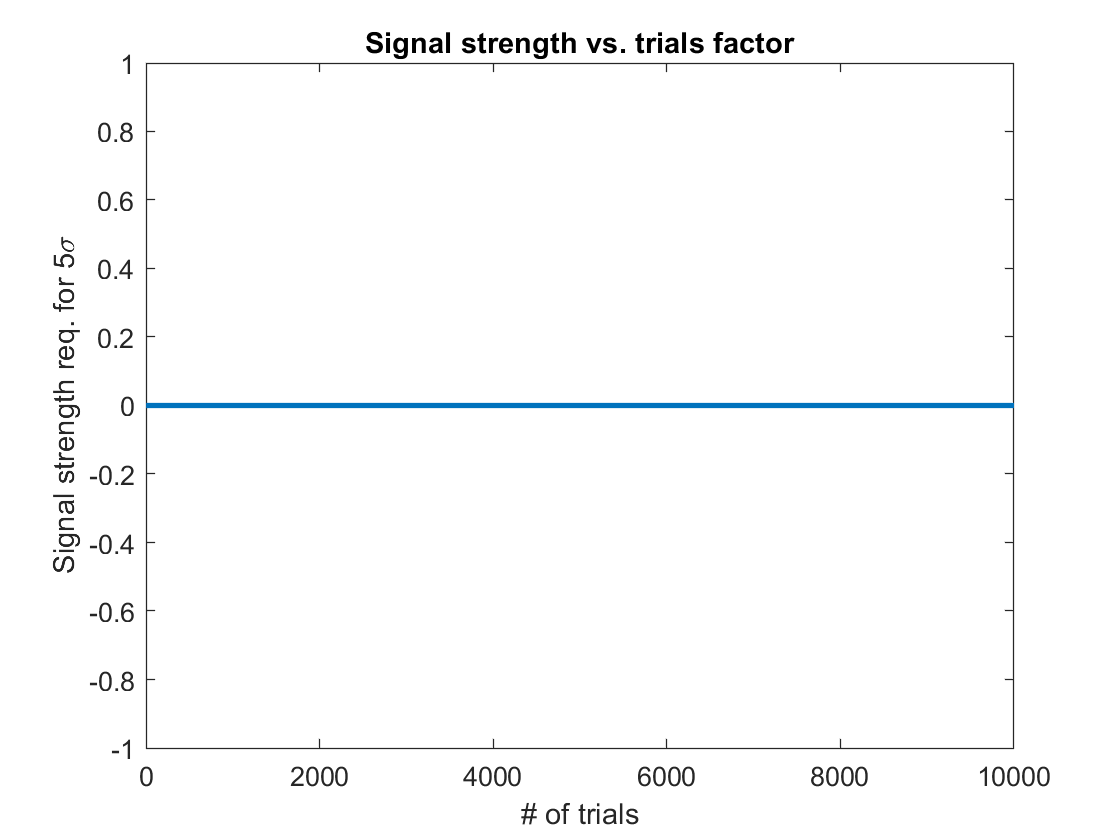


trials = logspace(0, 4, 1000);
signal_strength = @(trials) abs(icdf('chi2', p ./ trials, 0, 3));
clf;
plot(trials, signal_strength(trials), 'linewidth', 2);
title('Signal strength vs. trials factor')
xlabel('# of trials');
ylabel('Signal strength req. for 5{\sigma}')

function [pdfxs, pdfys] = pdfplot(xs,ys)
xs = linspace(min(xs), length(ys), length(ys));
pdfxs = linspace(min(xs), length(ys), 1000);
pdfys = interp1(xs, ys, pdfxs, 'nearest');
end

function [mu, sigma] = pdfstats(pdf)
[~, mu] = max(pdf);
sigma = (std(pdf) * length(pdf))^2;
end

function [rayxs, rayys] = rayleighconv(n, sigma);
    xs = 0:15;
    rayys_0 = raylpdf(xs, sigma);
    rayys = rayys_0;
    for ii = 1:n
        rayys = conv(rayys, rayys_0);
    end
    rayxs = linspace(0, 15, length(rayys));
end